# ISET3d: Assets

A scene's **assets** are the collection of objects and lights that are used in a PBRT scene.  The assets are stored in a recipe slot. Here we name our recipe object thisR, so they are stored in thisR.assets**,** which is a Matlab **tree** class.  Trees are a natural way to combine the description of objects with the transforms applied to those objects.  The nodes in the thisR.assets tree represent the assets (objects) and the transforms needed to render the assets.

The tree representation is simple.  It is a cell array of nodes (Node), each with a unique name, and a vector of integers (Parent) that specifies the identity of the parent node for every node.  

The @tree class has many methods for, say, visualizing the tree, grafting onto the tree, chopping off a branch, and so forth. 

The asset tree can be thought of as the branches and leaves.  Often, the  **branches**  represent transformations that control the position, orientation, and size of the objects.  These transformations are applied to all the objects below the branch. The **leaves** define the shape and material of the object.  In some cases, a branch may be an object and beneath it may be additional branches and leaves describing parts of that object.

This tutorial illustrates a few of the ways to control the properties and transforms of objects in an asset tree.  

The software interface is intended to make controlling the objects close to writing simple sentences.  The programming  consists of **set** and **get** commands that apply to the nodes of the tree. These have the form 

or

ISET3d Methods illustrated in this script are

**See also **

    t_piSceneInstances.m, t_assetsMotion.m, t_materials.m

## The simple scene

This simple scene has about 25 objects and is useful for demonstrating ISET3d programming.  Here is a low resolution rendering of the scene.  

ieInit;
if ~piDockerExists, piDockerConfig; end

thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 7 materials and 1 textures.
Attribute processing: Identified 9 assets; parsed up to line 103


We set a low resolution for speed.

thisR.set('film resolution',[200 150]*2);
thisR.set('rays per pixel',64*4);
thisR.set('fov',45);
thisR.set('nbounces',4)

ans =   recipe with properties:

                  name: 'SimpleScene'
                camera: [1×1 struct]
               sampler: [1×1 struct]
                  film: [1×1 struct]
                filter: []
            integrator: [1×1 struct]
              renderer: []
                lookAt: [1×1 struct]
                 scale: [0×3 double]
                 world: {'WorldBegin'}
                lights: []
        transformTimes: []
             inputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/data/scenes/SimpleScene/SimpleScene.pbrt'
            outputFile: '/Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/SimpleScene.pbrt'
          renderedFile: ''
               version: 4
             materials: [1×1 struct]
              textures: [1×1 struct]
                assets: [1×1 tree]
              exporter: 'PARSE'
                 media: []
              metadata: [1×1 struct]
             recipeVer: 2
 

## Render the scene

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (3.99 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 6.82 sec
Pull: rsync -r  wandell@muxreconrt.s

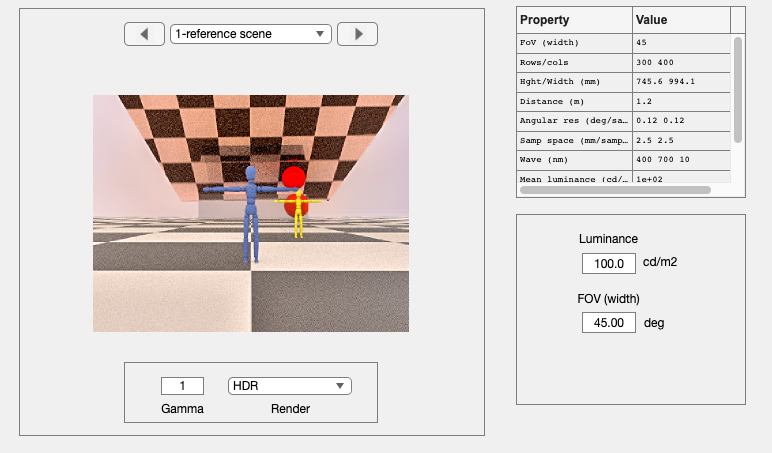

piWRS(thisR,'name', 'reference scene', ...
    'render flag','hdr');

## The asset tree

The recipe **thisR** contains the **assets** tree.  This is a simple tree with only a few assets.

thisR.assets

ans =   tree with properties:

                   Node: {27×1 cell}
                 Parent: [27×1 double]
        mapFullName2Idx: [27×1 containers.Map]
       mapShortName2Idx: [26×1 containers.Map]
     mapLgtFullName2Idx: [4×1 containers.Map]
    mapLgtShortName2Idx: [4×1 containers.Map]


You can display the tree data in several ways, using the show command.  By default, calling thisR.show opens a window to the top level of the tree. By clicking on the black triangles, you can explore different depths of the tree.

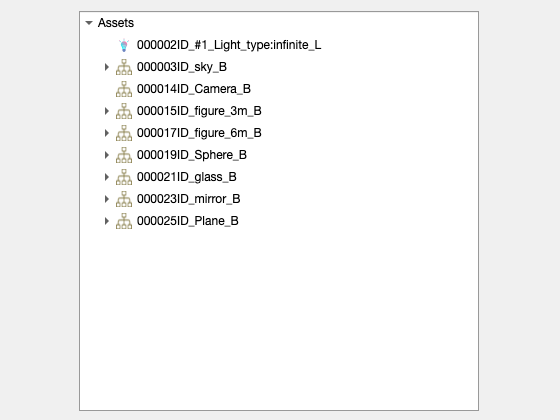

assetTree = thisR.assets.show;

You can also print the asset tree structure in the command window

thisR.assets.print;

                                                                                                                     000001ID..oot_B                                                                                                                     
        +------------------------------------------------------------+-----------------------------------------------------+-------+-----------------+-----------------+-----------------+-----------------+-----------------+-----------------+         
        |                                                            |                                                             |                 |                 |                 |                 |                 |                 |         
 000002ID..ite_L                                              000003ID..sky_B                                               000014ID..era_B   000015ID.._3m_B   000017ID.._6m_B   000019ID..ere_B   000021ID..ass_B   000023ID..ror_B   000025ID..ane_B  


You can also visualize the positions of the assets this way

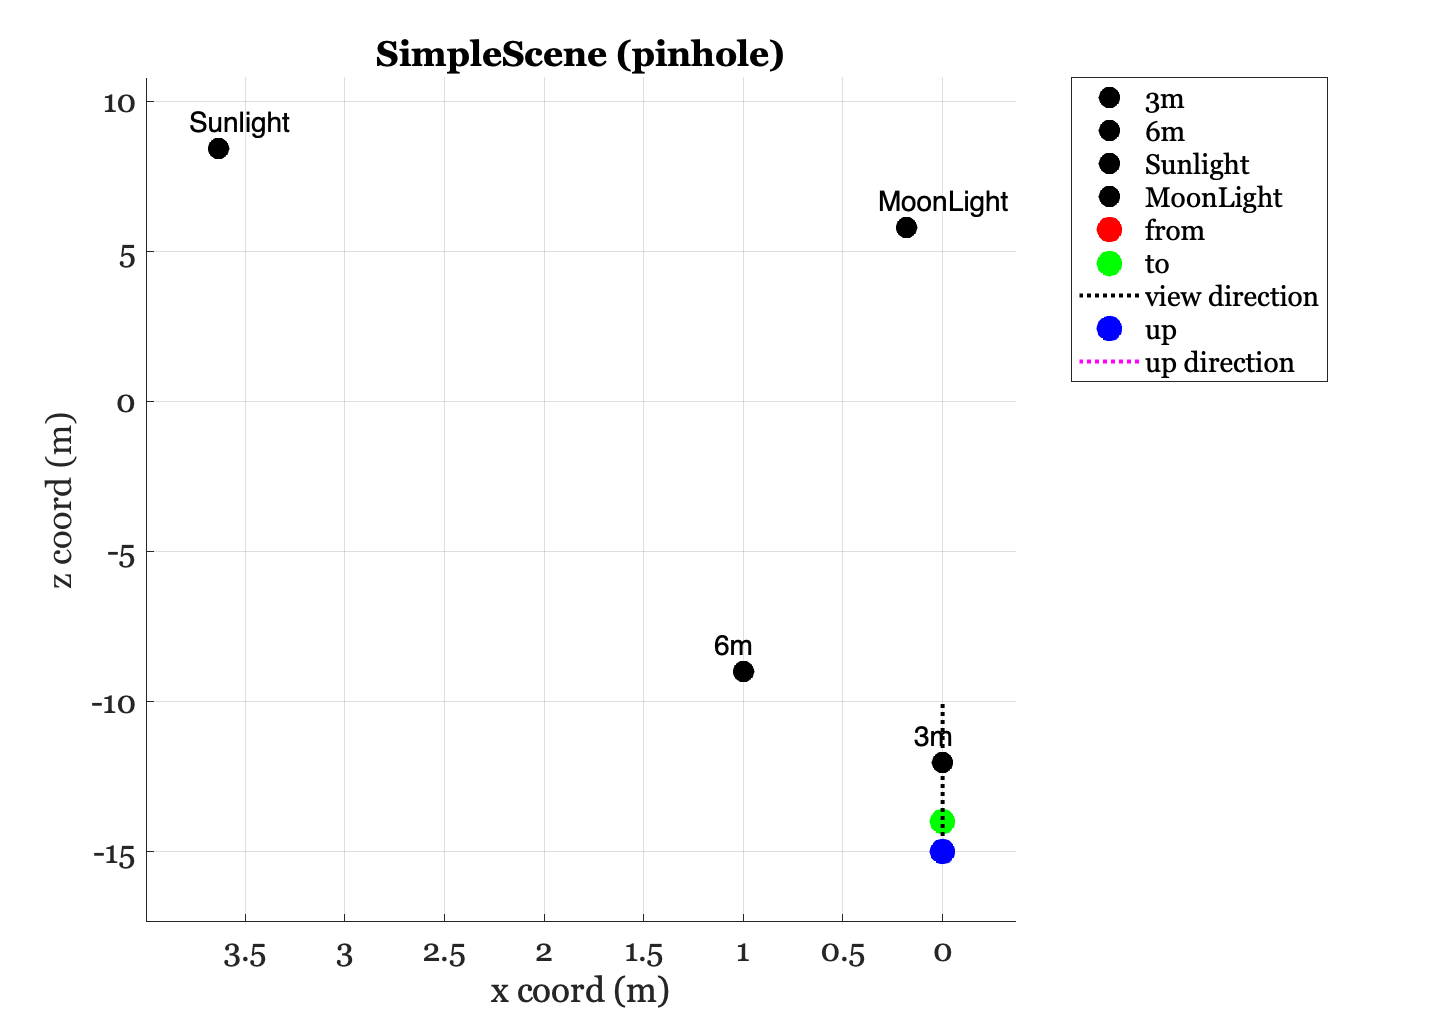

piAssetGeometry(thisR);

## Tree methods 

There are many tree methods that can be applied to the assets.  Here are a few examples.

## Referring to an object

You can get the index into the asset tree for a particular object if you know the object's name.  The full asset names are quite long and formatted as **XXXXID_MoreComplicatedInfo_AssetName_Type**.  You do not need to know all of this information when you find the index.  You can just use **piAssetSearch.**

Here is a simple case.  There are two objects in the scene, one that is a figure 3m away and another a figure that is 6m away.  

thisR.show('objects');


----- Summary of recipe: SimpleScene

                   index      material          positions (m)             sizes (m)      
                   _____    _____________    ____________________    ____________________

    figure_3m_O     16      {'uber_blue'}    {'0.00 0.50 -12.03'}    {'1.02 1.00 0.17'  }
    figure_6m_O     18      {'uber'     }    {'1.00 0.50 -9.00' }    {'1.02 1.00 0.17'  }
    Sphere_O        20      {'BODY'     }    {'3.63 1.14 8.43'  }    {'2.00 2.00 2.00'  }
    glass_O         22      {'GLASS'    }    {'0.18 0.91 5.79'  }    {'8.00 2.00 0.00'  }
    mirror_O        24      {'mirror'   }    {'0.47 4.30 3.01'  }    {'13.42 3.51 16.17'}
    Plane_O         27      {'Material' }    {'0.00 0.00 0.00'  }    {'50.00 0.00 50.00'}

F

The closer one is blue.  We can find the index to it because we know the names.

blueIDX = piAssetSearch(thisR,'object name','figure_3m');
thisR.get('node',blueIDX, 'world position')

ans =          0    0.5000  -12.0281


## Rotate the blue man

The implementation is designed to simplfy changing the position, orientation or other properties of an object.  For example, the blue man is stored in a node that includes the string 'figure_3m'. We use piAssetSearch to find the index into that object node.  Then we rotate the object with this 'set' command

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (2.10 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 6.37 sec
Pull: rsync -r  wandell@muxreconrt.s

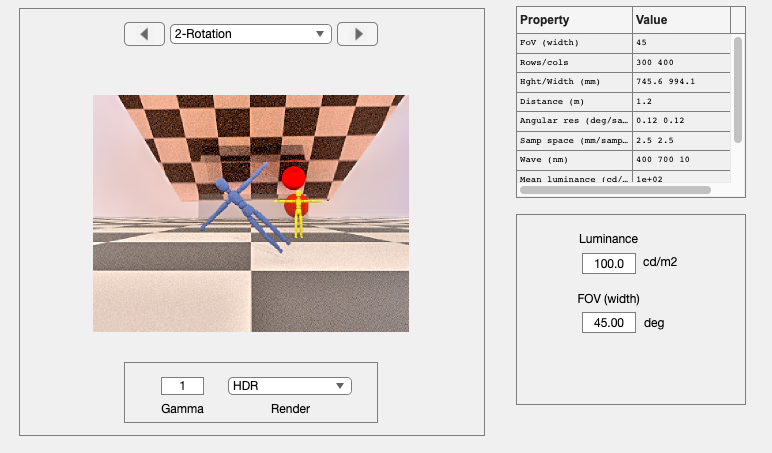

thisR.set('node', blueIDX, 'rotate', [0, 0, 45]);
piWRS(thisR, 'render type', 'radiance', ...
    'name', 'Rotation');

## Translate

The yellow man's position in the world can be translated this way.

yellowIDX = piAssetSearch(thisR,'object name','figure_6m');
thisR.set('node', yellowIDX, 'translate', [0, 0, -2]);
piWRS(thisR, ...
    'render type', 'radiance', ...
    'name', 'Translation');

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (1.73 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 7.22 sec
Pull: rsync -r  wandell@muxreconrt.s

## Scale

We increase the size of the yellow man

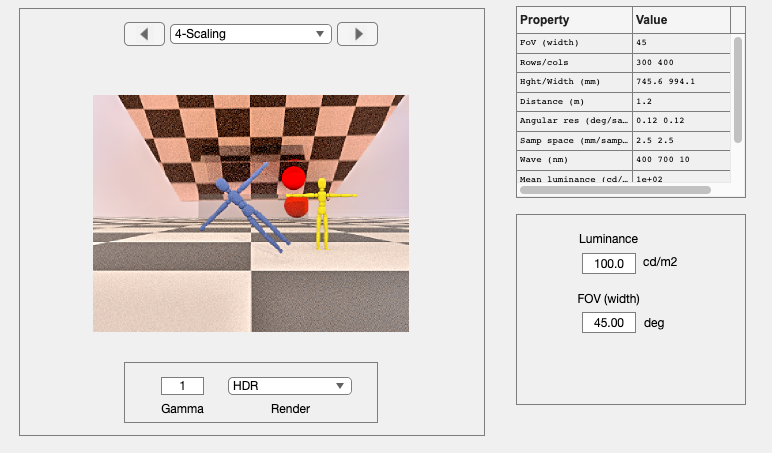

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (1.46 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 6.16 sec
Pull: rsync -r  wandell@muxreconrt.s

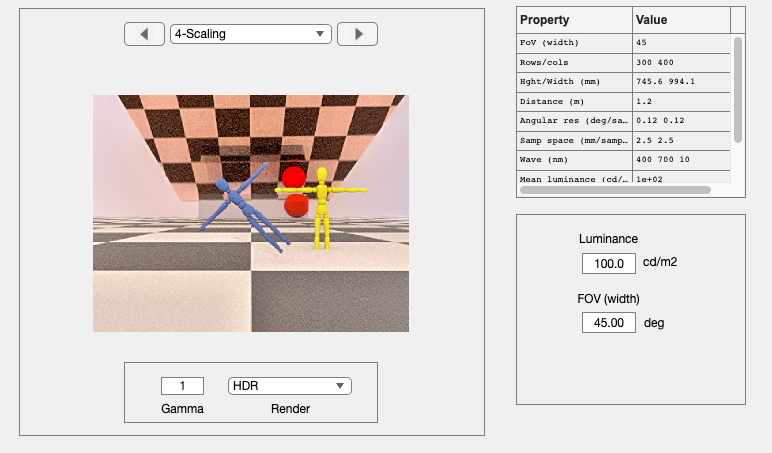

thisR.set('node', yellowIDX, 'scale', 1.3);
piWRS(thisR, 'render type', 'radiance', ...
    'name', 'Scaling');

## Add an object into a scene

We have test charts and other assets stored as recipes that can be merged into a scene.  Here we add the famous "Stanford Bunny" to our scene:

bunny = piAssetLoad('bunny');

thisR = piRecipeMerge(thisR,bunny.thisR,'node name',bunny.mergeNode,'object instance', false);

Copied resources from:
/Users/wandell/Documents/MATLAB/iset3d-v4/data/scenes/bunny 
to 
/Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene 
 



% scale the bunny so we can see it
thisR.show('objects');


----- Summary of recipe: SimpleScene

                       index      material          positions (m)             sizes (m)      
                       _____    _____________    ____________________    ____________________

    figure_3m_O         16      {'uber_blue'}    {'0.00 0.50 -12.03'}    {'1.02 1.00 0.17'  }
    figure_6m_O         18      {'uber'     }    {'1.00 0.50 -11.00'}    {'1.32 1.30 0.22'  }
    Sphere_O            20      {'BODY'     }    {'3.63 1.14 8.43'  }    {'2.00 2.00 2.00'  }
    glass_O             22      {'GLASS'    }    {'0.18 0.91 5.79'  }    {'8.00 2.00 0.00'  }
    mirror_O            24      {'mirror'   }    {'0.47 4.30 3.01'  }    {'13.42 3.51 16.17'}
    Plane_O             27      {'Material' }    {'0.00 0.00 0.0

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (2.72 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 6.31 sec
Pull: rsync -r  wandell@muxreconrt.s

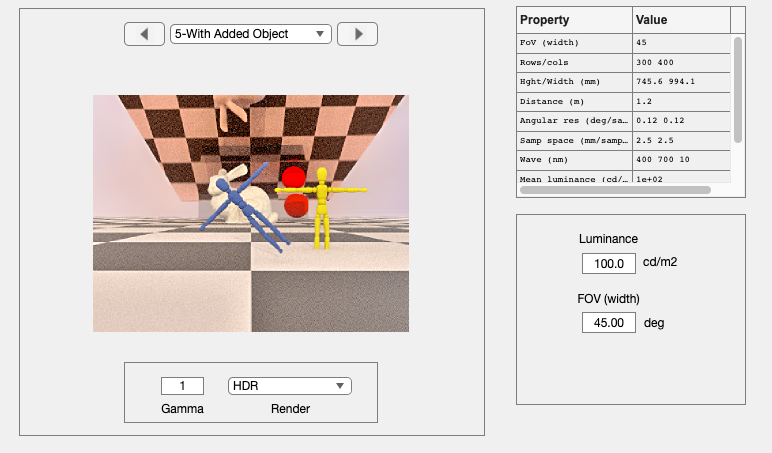


bunnyIDX = piAssetSearch(thisR,'object name','Bunny');
thisR.recipeSet('asset', bunnyIDX, 'scale',[12 12 12]*5);

% s = thisR.get('asset',bunnyName,'scale');

bPos = thisR.get('asset',blueIDX,'world position');

thisR.set('asset',bunnyIDX,'world position',bPos + [0 0 2]);
piWRS(thisR,'name','With Added Object');

## Delete an object

Let's remove the blue man so we can see the bunny more clearly.

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/SimpleScene/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/SimpleScene/ ...
Done (4.75 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15988 sh -c "cd /iset/iset3d-v4/local/SimpleScene && rm -rf renderings/{*,.*}  &&  cp -n -r geometry/* /ISETResources/geometry ; rm -rf geometry ; ln -s /ISETResources/geometry geometry ;  cp -n -r textures/* /ISETResources/textures ; rm -rf textures ; ln -s /ISETResources/textures textures ; cp -n -r spds/* /ISETResources/spds ; rm -rf spds ; ln -s /ISETResources/spds spds ; cp -n -r lights/* /ISETResources/lights ; rm -rf lights ; ln -s /ISETResources/lights lights ; cp -n -r skymaps/* /ISETResources/skymaps ; rm -rf skymaps ; ln -s /ISETResources/skymaps skymaps  && pbrt --gpu --outfile renderings/SimpleScene.exr SimpleScene.pbrt "
Rendered remotely in: 6.50 sec
Pull: rsync -r  wandell@muxreconrt.s

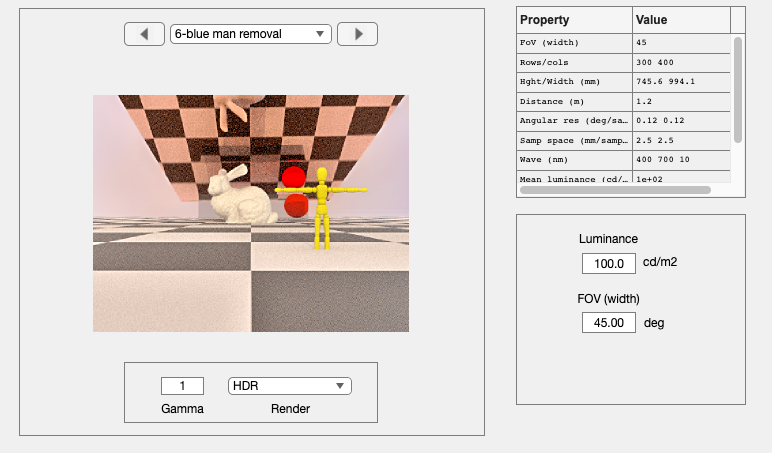

thisR.set('node',blueIDX,'delete'); 
scene = piWRS(thisR,'name','blue man removal');